# **Design Project 5 – Digital Equivalent of Project 2 Lead–Lag Compensator**

s = tf('s');

%% 1.  Continuous-time plant used in Project 2 (chemical process)
Gp = 200 / (s * (s + 6) * (s + 10));           
%% 2.  Best analogue compensator from Project 2
%     Lead stage (bisector method)              
C_lead = (s + 4) / (s + 20);                   % z_lead = −4,  p_lead = −20
%     Lag stage                                 
C_lag  = (s + 0.05) / (s + 0.005);             % z_lag  = −0.05, p_lag = −0.005
%     Gain chosen by magnitude condition at desired pole
p_d    = -3.6892 + 6.1093j;                    % desired dominant pole
Kc     = abs( 1 / evalfr(C_lead * Gp, p_d) );  % same line as Project 2
C_best = Kc * C_lead * C_lag;                  % complete compensator

fprintf('Computed gain Kc = %.4f\n', Kc);

Computed gain Kc = 5.8291


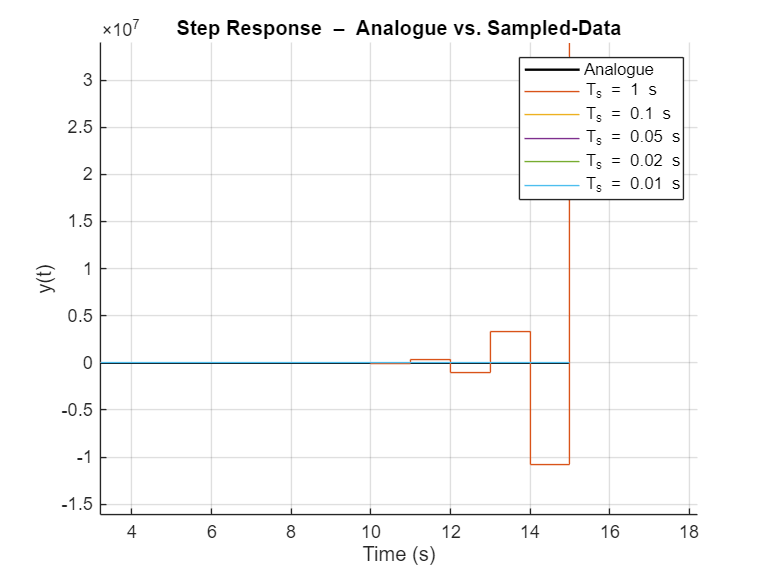


%% 3.  Reference analogue closed loop
CLc  = feedback(C_best * Gp, 1);
t_a  = 0:0.001:15;
y_a  = step(CLc, t_a);

%% 4.  Sampling-period sweep & Jury stability
Ts_vec   = [1  0.1  0.05  0.02  0.01];   % s
matchTol = 0.05;                         % 5 % RMS error wrt analogue
juryOK   = false(size(Ts_vec));          % pre-alloc
rmsErr   = zeros(size(Ts_vec));

figure(10);  hold on;  grid on;
plot(t_a, y_a, 'k', 'LineWidth',1.3, 'DisplayName','Analogue');

for k = 1:numel(Ts_vec)
    Ts  = Ts_vec(k);

    % -- Discretise plant (ZOH) & compensator (Tustin)
    Gz  = c2d(Gp,  Ts, 'zoh');
    Cz  = c2d(C_best, Ts, 'tustin');

    % -- Digital closed loop
    CLd = feedback(Cz * Gz, 1);

    % -- Jury test on denominator
    [~, den_z] = tfdata(CLd,'v');
    juryOK(k)  = juryTest(den_z);

    %% ----- Step response (same 15-s horizon as analogue)
    t_d = 0:Ts:15;
    [y_d, t_out] = step(CLd, t_d);   % ask for BOTH y and t
    y_d   = squeeze(y_d);            % drop singleton dims → column vector
    y_ref = interp1(t_a, y_a, t_out, 'linear');  % column vector

% ----- Plot
stairs(t_out, y_d, ...
       'DisplayName',['T_s = ' num2str(Ts,'%g') ' s']);

% ----- RMS error (vectors now have identical orientation)
rmsErr(k) = sqrt( mean( (y_ref - y_d).^2 ) );


    if rmsErr(k) < matchTol && juryOK(k)
        goodTs = Ts;         % first Ts that meets both criteria
        break
    end
end

title('Step Response  –  Analogue vs. Sampled-Data');
xlabel('Time (s)');  ylabel('y(t)');  legend('show');

xlim([3.2 18.2])
ylim([-16062019 33937981])


%% 5.  Summary table
disp(' ');

T = table(Ts_vec(:).', rmsErr(:).', juryOK(:).',...
          'VariableNames', {'T_s [s]','RMS error','Jury stable'});
disp(T);

                 T_s [s]                                           RMS error                                         Jury stable           
    _________________________________    _____________________________________________________________    _________________________________

    1     0.1    0.05    0.02    0.01    9.084e+06     0.020541    0.0094103    0.0035946    0.0017714    false  false  false  false  false




if exist('goodTs','var')
    fprintf('✔  Sampling period T_s = %.3f s satisfies ≤5 %% error and passes Jury stability.\n',goodTs);
else
    fprintf('✖  None of the tested sampling periods met **both** accuracy and stability criteria.\n');
end

✖  None of the tested sampling periods met **both** accuracy and stability criteria.
